# GNC Preliminary Calculations & Derivations

Used for intial sizing of spacecraft actuators. More detailed analysis to come as we get better models.

All masses in kilograms (kg), all spacecraft dimensions in meters (m), and all orbital distances/altitudes/parameters in kilometers (km).

## Constants Setup

% Lunar parameters
mu = 4.902800118E03; % kg/m^3 (I forget)
R = 1737.4; % km
gEarth = 9.81 % m/s^2

gEarth = 9.8100

## Instrument Setup

NFOV.pixelPitch = 6.4; % micro m
NFOV.focalLength = 1.3; % m
NFOV.pixels = [5120, 3840]; % width, height

## Orbit Parameters

cicularLow.peri  = 18; cicularLow.apo = 18; % km
cicrcularHigh.peri  = 90; circularHigh.apo = 90; % km
elliptical.peri = 18; elliptical.apo = 90; % km

#### Thrusters

RCSthruster.force = convforce(5, 'lbf', 'N')

RCSthruster = struct with fields:
    force: 22.2411



engineMain.force = convforce(100, 'lbf', 'N')

engineMain = struct with fields:
    force: 444.8222


## Attitude Parameters

### Setup

% spacecraft parameters
sc.mass = 700; % kg, max mass
% sc.m = 635; % kg, current WET mass
bus.length = .1; % m
bus.width = .112; % m
bus.height = .14; % m

% solar arrays
solar.mass = 6.485584158; % kg
solar.Area = 2.06; % m^2

Rough Layout:

## 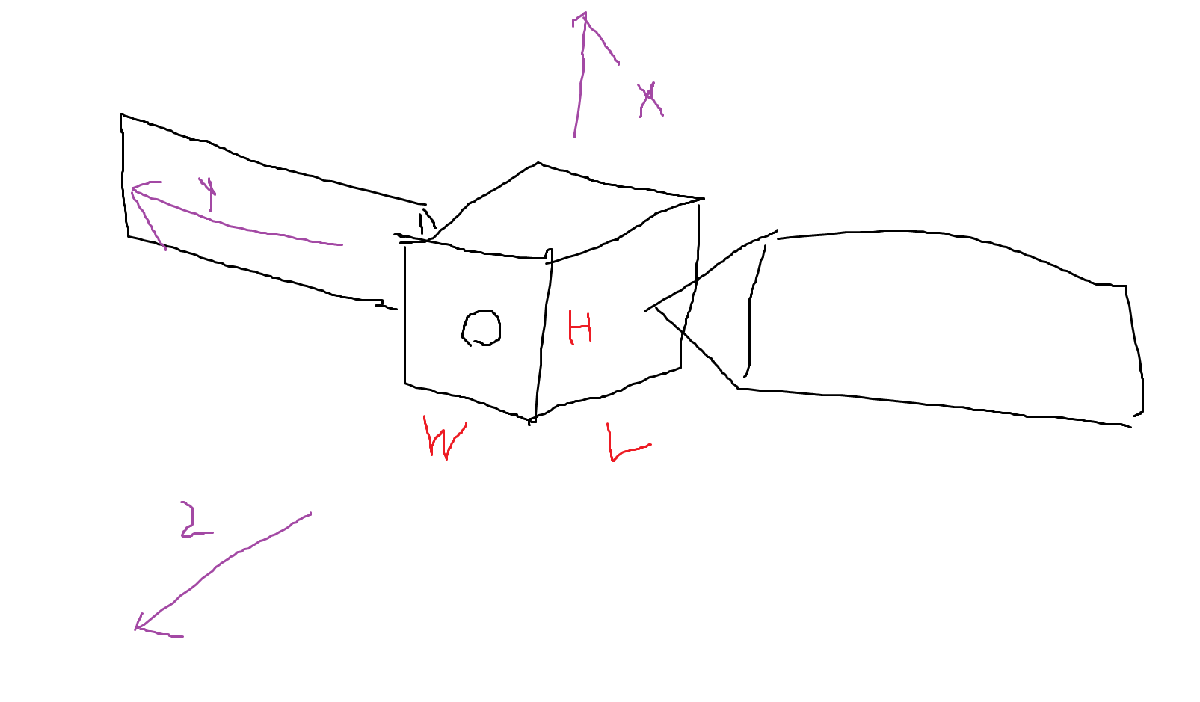

### Attitude Parameter (CG, MoI, etc) Derivations

Solar panel sizing. Only looking at DEPLOYED solar panels for now, as they should be the more challenging case.

solar.height = bus.height; % m
% solar.length = (solar.Area / 2) / solar.height; % m
solar.length = 1.7; % m, from discussion with Ben Slama, EPS lead
solar.depth = 1/100; % 1 cm -> m
solar.offset = 10/100; % 10 cm -> m
solar

solar = struct with fields:
      mass: 6.4856
      Area: 2.0600
    height: 0.1400
    length: 1.7000
     depth: 0.0100
    offset: 0.1000
        cg: [1×1 struct]


Center of Mass Computation

bus.mass = sc.mass - solar.mass

bus = struct with fields:
    length: 0.1000
     width: 0.1120
    height: 0.1400
      mass: 693.5144
        cg: [1×1 struct]



bus.cg.x_M = bus.width/2;
bus.cg.y_M = bus.length/2;
bus.cg.z_M = bus.height/2;
bus.cg

ans = struct with fields:
    x_M: 0.0560
    y_M: 0.0500
    z_M: 0.0700



solar.cg.note = "Solar panel cg measured from bus MECHANICAL frame";
solar.cg.x_M = bus.cg.x_M;
solar.cg.y_M = bus.length - solar.depth/2;
solar.cg.z_M = bus.cg.z_M;
solar.cg

ans = struct with fields:
    note: "Solar panel cg measured from bus MECHANICAL frame"
     x_M: 0.0560
     y_M: 0.0950
     z_M: 0.0700



sc.cg.x_M = bus.cg.x_M;
sc.cg.y_M = (2*(solar.mass*solar.cg.y_M) + bus.mass*bus.cg.y_M)/sc.mass;
sc.cg.z_M = bus.cg.z_M;
sc.cg

ans = struct with fields:
    x_M: 0.0560
    y_M: 0.0513
    z_M: 0.0700


Moments of Inertia (MOI)

Assume evenly distributed mass across rectangular prism spacecraft and solar panels. Solar panels are to be fixed at the BACK of the spacecraft for now. Later will want ability to do it when rotated as well. As a reminder:

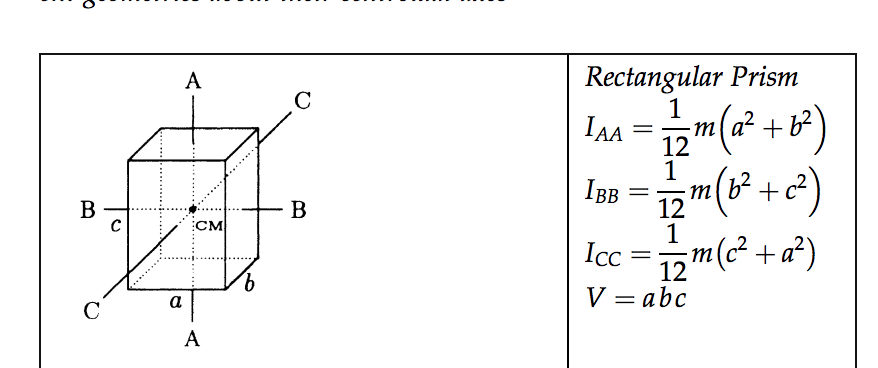

% solar panel moments of inertia
Ix_solar = 1/12*solar.mass*(solar.depth^2 + solar.length^2)

Ix_solar = 1.5620

Iy_solar = 1/12*solar.mass*(solar.height^2 + solar.depth^2)

Iy_solar = 0.0106

Iz_solar = 1/12*solar.mass*(solar.height^2 + solar.length^2)

Iz_solar = 1.5725


% bus moments of inertia
Ix_bus = 1/12*bus.mass*(bus.width^2 + bus.length^2)

Ix_bus = 1.3029

Iy_bus = 1/12*bus.mass*(bus.height^2 + bus.length^2)

Iy_bus = 1.7107

Iz_bus = 1/12*bus.mass*(bus.height^2 + bus.width^2)

Iz_bus = 1.8577


% spacecraft moment of inertia
rxy_bus = sqrt( (bus.cg.x_M - sc.cg.x_M)^2 + (bus.cg.y_M - sc.cg.y_M)^2)

rxy_bus = 0.0013

ryz_bus = sqrt( (bus.cg.y_M - sc.cg.y_M)^2 + (bus.cg.z_M - sc.cg.z_M)^2)

ryz_bus = 0.0013

rxz_bus = sqrt( (bus.cg.x_M - sc.cg.x_M)^2 + (bus.cg.z_M - sc.cg.z_M)^2)

rxz_bus = 0


rxy_solar = sqrt( (solar.cg.x_M - sc.cg.x_M)^2 + (solar.cg.y_M - sc.cg.y_M)^2)

rxy_solar = 0.0437

ryz_solar = sqrt( (solar.cg.y_M - sc.cg.y_M)^2 + (solar.cg.z_M - sc.cg.z_M)^2)

ryz_solar = 0.0437

rxz_solar = sqrt( (solar.cg.x_M - sc.cg.x_M)^2 + (solar.cg.z_M - sc.cg.z_M)^2)

rxz_solar = 0


sc.MoI.x_B = (Ix_bus + bus.mass*ryz_bus^2) + 2*(Ix_solar + solar.mass*ryz_solar^2);
sc.MoI.y_B = (Iy_bus + bus.mass*rxz_bus^2) + 2*(Iy_solar + solar.mass*rxz_solar^2);
sc.MoI.z_B = (Iz_bus + bus.mass*rxy_bus^2) + 2*(Iz_solar + solar.mass*rxy_solar^2);
sc.MoI

ans = struct with fields:
    x_B: 4.4528
    y_B: 1.7320
    z_B: 5.0287


## Orbit Requirements

### Uncertainty Growth

TODO stm on initial covariance

### Accelerometer Math

#### Derivations

RCS thrusters

numFiringIn1Dir = 3;
accelMax = 1.2 * numFiringIn1Dir * RCSthruster.force / sc.mass % m/s^2

accelMax = 0.1144

accelMax/gEarth

ans = 0.0117

Main Engine

accelMax = 1.2 * engineMain.force / sc.mass % m/s^2

accelMax = 0.7626

accelMax/gEarth

ans = 0.0777

## Attitude Requirements

### Slew Requirements

180 flip about imaging axis in 30 minutes

dt = 30*60 /2 

dt = 900

torqueMax = 1.2 * (4/dt^2 * sc.MoI.z_B * deg2rad(180)) % Nm

torqueMax = 9.3619e-05

fprintf("max torque in mNm: %f", torqueMax*1e3)

max torque in mNm: 0.093619

### INSTR Math

#### Derivations

Deriving instrument parameters

NFOV.angularResolution = NFOV.pixelPitch*1E-6/NFOV.focalLength; % radians
NFOV.fov.width = NFOV.angularResolution*NFOV.pixels(1);
NFOV.fov.height = NFOV.angularResolution*NFOV.pixels(2);

rad2deg(NFOV.angularResolution)

ans = 2.8207e-04

rad2deg(NFOV.fov.width)

ans = 1.4442

rad2deg(NFOV.fov.height)

ans = 1.0832

Deriving imaging parameters at various altitudes

% error = 3*deg2rad(.01); 
error = 3*deg2rad(60/3600); % 3 sigma of 60 arc seconds

High resolution imaging, 20 km

img.height = 2*elliptical.peri*tan(NFOV.fov.height/2); % km
img.width  = 2*elliptical.peri*tan(NFOV.fov.width/2) % km

img = struct with fields:
    height: 0.3403
     width: 0.4537


delta = elliptical.peri*tan(error) % km

delta = 0.0157

pcntShift.height = (delta)/img.height;
pcntShift.width  = delta/img.width

pcntShift = struct with fields:
    height: 0.0462
     width: 0.0346



% TODO: incorporate movement
% TODO: determine if we're doing height along orbit or width along orbit

Low resolution imaging, 100 km

img.height = 2*elliptical.apo*tan(NFOV.fov.height/2); % km
img.width  = 2*elliptical.apo*tan(NFOV.fov.width/2) % km

img = struct with fields:
    height: 1.7015
     width: 2.2687


delta = elliptical.apo*tan(error) % km

delta = 0.0785

pcntShift.height = delta/img.height;
pcntShift.width  = delta/img.width

pcntShift = struct with fields:
    height: 0.0462
     width: 0.0346



% TODO: incorporate movementx